% ANALYSE COMPARATIVE DES SYNERGIES MUSCULAIRES - 3 POPULATIONS
% Chargement des données
W_post = Profilglobalsynergiespost;  % Groupe post-opératoire (20 sujets)
W_asymp = Profilglobalsynergies;     % Groupe asymptomatique (20 sujets)
W_pre = Profilglobalsynergiespr;     % Groupe pré-opératoire (20 sujets)

% Activations temporelles
H_asymp = Profilglobalactivations;   % Activations asymptomatiques
H_post = Profilglobalactivationspost; % Activations post-opératoires
H_pre = Profilglobalactivationspr;   % Activations pré-opératoires

% noms_muscles = {'Anterior deltoid', 'Middle deltoid', 'Posterior deltoid', ...
%                 'Middle trapezius', 'Upper trapezius', 'Anterior serratus'};

noms_muscles = {'Ant delt', 'Mid delt', 'Post delt', ...
                'Mid trap', 'Up trap', 'Ant serra'};

% Nombre de sujets dans chaque groupe
n_subjects = 20;

% ---- EXTRACTION DES SYNERGIES ----
% Fonction pour extraire les synergies
extract_synergies = @(W, n) deal(W(:, 1:2:end), W(:, 2:2:end));

[synergy1_post, synergy2_post] = extract_synergies(W_post, n_subjects);
[synergy1_asymp, synergy2_asymp] = extract_synergies(W_asymp, n_subjects);
[synergy1_pre, synergy2_pre] = extract_synergies(W_pre, n_subjects);

% ---- EXTRACTION DES ACTIVATIONS TEMPORELLES  ----
% Fonction améliorée pour extraire les activations
extract_activations_improved = @(H, n_subjects) extract_activations_helper(H, n_subjects);

[activation1_asymp, activation2_asymp] = extract_activations_improved(H_asymp, n_subjects);
[activation1_post, activation2_post] = extract_activations_improved(H_post, n_subjects);
[activation1_pre, activation2_pre] = extract_activations_improved(H_pre, n_subjects);

% ---- STATISTIQUES DESCRIPTIVES ----
t_val = tinv(0.975, n_subjects-1);

% Fonction pour calculer les statistiques
calc_stats = @(data) deal(...
    mean(data, 2), ...
    std(data, 0, 2), ...
    std(data, 0, 2) / sqrt(n_subjects), ...
    t_val * std(data, 0, 2) / sqrt(n_subjects));

% Synergies
[mean_syn1_post, std_syn1_post, sem_syn1_post, IC_syn1_post] = calc_stats(synergy1_post);
[mean_syn2_post, std_syn2_post, sem_syn2_post, IC_syn2_post] = calc_stats(synergy2_post);
[mean_syn1_asymp, std_syn1_asymp, sem_syn1_asymp, IC_syn1_asymp] = calc_stats(synergy1_asymp);
[mean_syn2_asymp, std_syn2_asymp, sem_syn2_asymp, IC_syn2_asymp] = calc_stats(synergy2_asymp);
[mean_syn1_pre, std_syn1_pre, sem_syn1_pre, IC_syn1_pre] = calc_stats(synergy1_pre);
[mean_syn2_pre, std_syn2_pre, sem_syn2_pre, IC_syn2_pre] = calc_stats(synergy2_pre);

% Activations
[mean_act1_post, std_act1_post, sem_act1_post, IC_act1_post] = calc_stats(activation1_post);
[mean_act2_post, std_act2_post, sem_act2_post, IC_act2_post] = calc_stats(activation2_post);
[mean_act1_asymp, std_act1_asymp, sem_act1_asymp, IC_act1_asymp] = calc_stats(activation1_asymp);
[mean_act2_asymp, std_act2_asymp, sem_act2_asymp, IC_act2_asymp] = calc_stats(activation2_asymp);
[mean_act1_pre, std_act1_pre, sem_act1_pre, IC_act1_pre] = calc_stats(activation1_pre);
[mean_act2_pre, std_act2_pre, sem_act2_pre, IC_act2_pre] = calc_stats(activation2_pre);


% ---- TESTS ANOVA À UN FACTEUR ----

% Initialisation des résultats ANOVA
anova_results = struct();
anova_results.syn1_p = zeros(6,1);
anova_results.syn1_F = zeros(6,1);
anova_results.syn2_p = zeros(6,1);
anova_results.syn2_F = zeros(6,1);

fprintf('\n=== TESTS ANOVA À UN FACTEUR ===\n');


=== TESTS ANOVA À UN FACTEUR ===


fprintf('Muscle\t\t\tSynergie 1\t\t\tSynergie 2\n');

Muscle			Synergie 1			Synergie 2


fprintf('\t\t\tF\tp-value\t\tF\tp-value\n');

			F	p-value		F	p-value



% Tests ANOVA pour chaque muscle
for muscle = 1:6
    % Préparation des données pour ANOVA - Synergie 1
    data_syn1 = [synergy1_asymp(muscle,:)'; synergy1_pre(muscle,:)'; synergy1_post(muscle,:)'];
    group_syn1 = [ones(n_subjects,1); 2*ones(n_subjects,1); 3*ones(n_subjects,1)];
    
    % Préparation des données pour ANOVA - Synergie 2
    data_syn2 = [synergy2_asymp(muscle,:)'; synergy2_pre(muscle,:)'; synergy2_post(muscle,:)'];
    group_syn2 = [ones(n_subjects,1); 2*ones(n_subjects,1); 3*ones(n_subjects,1)];
    
    % ANOVA à un facteur - Synergie 1
    [p_syn1, tbl_syn1] = anova1(data_syn1, group_syn1, 'off');
    F_syn1 = tbl_syn1{2,5}; % Valeur F
    
    % ANOVA à un facteur - Synergie 2
    [p_syn2, tbl_syn2] = anova1(data_syn2, group_syn2, 'off');
    F_syn2 = tbl_syn2{2,5}; % Valeur F
    
    % Stockage des résultats
    anova_results.syn1_p(muscle) = p_syn1;
    anova_results.syn1_F(muscle) = F_syn1;
    anova_results.syn2_p(muscle) = p_syn2;
    anova_results.syn2_F(muscle) = F_syn2;
    
    % Affichage des résultats
    fprintf('%-15s\t%.2f\t%.3f%s\t\t%.2f\t%.3f%s\n', ...
        noms_muscles{muscle}, ...
        F_syn1, p_syn1, ternary(p_syn1 < 0.05, ' *', ''), ...
        F_syn2, p_syn2, ternary(p_syn2 < 0.05, ' *', ''));
end

Ant delt       	0.58	0.563		1.51	0.229
Mid delt       	1.07	0.351		2.66	0.079
Post delt      	11.11	0.000 *		18.39	0.000 *
Mid trap       	1.42	0.251		0.41	0.662
Up trap        	20.75	0.000 *		18.51	0.000 *
Ant serra      	1.66	0.199		1.73	0.186


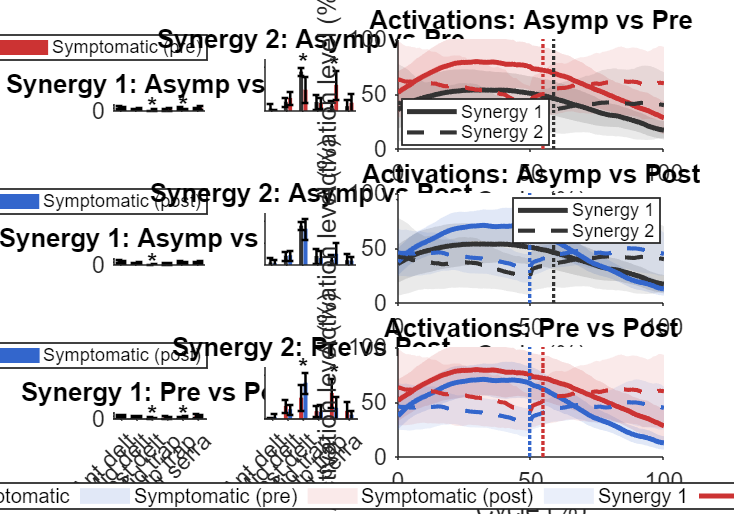


% ---- TESTS STATISTIQUES ----
% Initialisation des résultats
comparisons = {'Asymp vs Post', 'Asymp vs Pre', 'Pre vs Post'};
p_values = struct();
test_types = struct();

% Comparaisons pour Synergie 1
p_values.syn1_asymp_post = zeros(6,1);
p_values.syn1_asymp_pre = zeros(6,1);
p_values.syn1_pre_post = zeros(6,1);
test_types.syn1_asymp_post = strings(6,1);
test_types.syn1_asymp_pre = strings(6,1);
test_types.syn1_pre_post = strings(6,1);

% Comparaisons pour Synergie 2
p_values.syn2_asymp_post = zeros(6,1);
p_values.syn2_asymp_pre = zeros(6,1);
p_values.syn2_pre_post = zeros(6,1);
test_types.syn2_asymp_post = strings(6,1);
test_types.syn2_asymp_pre = strings(6,1);
test_types.syn2_pre_post = strings(6,1);

% Effectuer les tests pour chaque muscle
for muscle = 1:6
    % Synergie 1
    [p_values.syn1_asymp_post(muscle), test_types.syn1_asymp_post(muscle)] = ...
        perform_test_helper(synergy1_asymp(muscle,:)', synergy1_post(muscle,:)', noms_muscles{muscle}, 'Syn1 Asymp vs Post');
    
    [p_values.syn1_asymp_pre(muscle), test_types.syn1_asymp_pre(muscle)] = ...
        perform_test_helper(synergy1_asymp(muscle,:)', synergy1_pre(muscle,:)', noms_muscles{muscle}, 'Syn1 Asymp vs Pre');
    
    [p_values.syn1_pre_post(muscle), test_types.syn1_pre_post(muscle)] = ...
        perform_test_helper(synergy1_pre(muscle,:)', synergy1_post(muscle,:)', noms_muscles{muscle}, 'Syn1 Pre vs Post');
    
    % Synergie 2
    [p_values.syn2_asymp_post(muscle), test_types.syn2_asymp_post(muscle)] = ...
        perform_test_helper(synergy2_asymp(muscle,:)', synergy2_post(muscle,:)', noms_muscles{muscle}, 'Syn2 Asymp vs Post');
    
    [p_values.syn2_asymp_pre(muscle), test_types.syn2_asymp_pre(muscle)] = ...
        perform_test_helper(synergy2_asymp(muscle,:)', synergy2_pre(muscle,:)', noms_muscles{muscle}, 'Syn2 Asymp vs Pre');
    
    [p_values.syn2_pre_post(muscle), test_types.syn2_pre_post(muscle)] = ...
        perform_test_helper(synergy2_pre(muscle,:)', synergy2_post(muscle,:)', noms_muscles{muscle}, 'Syn2 Pre vs Post');
end

% ---- CRÉATION DE LA FIGURE PRINCIPALE AMÉLIORÉE ----
figure('Position', [50, 50, 2000, 1400]);

x_new = linspace(0, 100, 100);

% Couleurs améliorées pour une meilleure lisibilité
colors.asymp = [0.2, 0.2, 0.2];      % Asymptomatique - noir
colors.pre = [0.8, 0.2, 0.2];        % Pré-op - rouge
colors.post = [0.2, 0.4, 0.8];       % Post-op - bleu

% LIGNE 1: Asymp vs Pre
subplot(3, 4, 1);
plot_synergy_comparison_improved(mean_syn1_asymp, std_syn1_asymp, mean_syn1_pre, std_syn1_pre, ...
    p_values.syn1_asymp_pre, 'Synergy 1: Asymp vs Pre', colors.asymp, colors.pre, noms_muscles, false, 1);

subplot(3, 4, 2);
plot_synergy_comparison_improved(mean_syn2_asymp, std_syn2_asymp, mean_syn2_pre, std_syn2_pre, ...
    p_values.syn2_asymp_pre, 'Synergy 2: Asymp vs Pre', colors.asymp, colors.pre, noms_muscles, false, 2);

subplot(3, 4, [3 4]);
plot_activation_comparison_improved(x_new, mean_act1_asymp, std_act1_asymp, mean_act2_asymp, std_act2_asymp, ...
    mean_act1_pre, std_act1_pre, mean_act2_pre, std_act2_pre, ...
    'Activations: Asymp vs Pre', colors.asymp, colors.pre);

% LIGNE 2: Asymp vs Post
subplot(3, 4, 5);
plot_synergy_comparison_improved(mean_syn1_asymp, std_syn1_asymp, mean_syn1_post, std_syn1_post, ...
    p_values.syn1_asymp_post, 'Synergy 1: Asymp vs Post', colors.asymp, colors.post, noms_muscles, false, 5);

subplot(3, 4, 6);
plot_synergy_comparison_improved(mean_syn2_asymp, std_syn2_asymp, mean_syn2_post, std_syn2_post, ...
    p_values.syn2_asymp_post, 'Synergy 2: Asymp vs Post', colors.asymp, colors.post, noms_muscles, false, 6);

subplot(3, 4, [7 8]);
plot_activation_comparison_improved(x_new, mean_act1_asymp, std_act1_asymp, mean_act2_asymp, std_act2_asymp, ...
    mean_act1_post, std_act1_post, mean_act2_post, std_act2_post, ...
    'Activations: Asymp vs Post', colors.asymp, colors.post);

% LIGNE 3: Pre vs Post
subplot(3, 4, 9);
plot_synergy_comparison_improved(mean_syn1_pre, std_syn1_pre, mean_syn1_post, std_syn1_post, ...
    p_values.syn1_pre_post, 'Synergy 1: Pre vs Post', colors.pre, colors.post, noms_muscles, true, 9);

subplot(3, 4, 10);
plot_synergy_comparison_improved(mean_syn2_pre, std_syn2_pre, mean_syn2_post, std_syn2_post, ...
    p_values.syn2_pre_post, 'Synergy 2: Pre vs Post', colors.pre, colors.post, noms_muscles, true, 10);

subplot(3, 4, [11 12]);
plot_activation_comparison_improved(x_new, mean_act1_pre, std_act1_pre, mean_act2_pre, std_act2_pre, ...
    mean_act1_post, std_act1_post, mean_act2_post, std_act2_post, ...
    'Activations: Pre vs Post', colors.pre, colors.post);

% sgtitle('Comparative Analysis of Muscle Synergies - Three Populations', 'FontSize', 18, 'FontWeight', 'bold');

% Ajouter une légende globale en bas
h_legend = legend({'Asymptomatic', 'Symptomatic (pre)', 'Symptomatic (post)', ...
                   'Synergy 1', 'Synergy 2'}, ...
                   'Orientation', 'horizontal', ...
                   'FontSize', 12, ...
                   'Location', 'southoutside');
set(h_legend, 'Units', 'normalized', 'Position', [0.3, 0.01, 0.4, 0.05]);


% ---- RÉSUMÉ DES RÉSULTATS ----
fprintf('\n=== RÉSUMÉ DES COMPARAISONS STATISTIQUES ===\n');


=== RÉSUMÉ DES COMPARAISONS STATISTIQUES ===



% Tableau des p-values
create_summary_table(p_values, noms_muscles, anova_results, test_types);


=== TABLEAU RÉCAPITULATIF COMPLET ===

MUSCLE          | ANOVA        | ASYMP vs POST             | ASYMP vs PRE              | PRE vs POST               |
                | F(p-val)     | Test(p-val)               | Test(p-val)               | Test(p-val)               |

--- SYNERGIE 1 ---
Ant delt        | 0.58(0.563)  | Mann-Whitney(0.457)       | Mann-Whitney(0.267)       | Mann-Whitney(0.441)       |
Mid delt        | 1.07(0.351)  | Mann-Whitney(0.181)       | Mann-Whitney(0.298)       | Mann-Whitney(0.543)       |
Post delt       | 11.11(0.000*) | Welch(0.022*)             | Welch(0.000*)             | t-test(0.019*)            |
Mid trap        | 1.42(0.251)  | Mann-Whitney(0.394)       | Mann-Whitney(0.379)       | Mann-Whitney(0.108)    


% Corrélations entre profils
calculate_correlations(mean_syn1_asymp, mean_syn1_post, mean_syn1_pre, ...
                      mean_syn2_asymp, mean_syn2_post, mean_syn2_pre);


=== CORRÉLATIONS ENTRE PROFILS ===
Synergie 1:
  Asymp vs Post: r = 0.941
  Asymp vs Pre:  r = 0.446
  Pre vs Post:   r = 0.648
Synergie 2:
  Asymp vs Post: r = 0.978
  Asymp vs Pre:  r = 0.475
  Pre vs Post:   r = 0.643
